assert(isfile("DCS_3D_Hole.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

#### Electromagnet

EM.num = 1;
EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % (m)

EM_pos = [-22e-3, 0, 7.5e-3]; % (m)
EM = SetPositionRotation(EM, EM_pos, [1,0,0], deg2rad(20));

EM.current = 1; % (A)
EM.Nturns = 60;
EM.current_density = EM.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.angular_frequency = 2*pi*2000; % (rad/s)

#### Sensor

Sensor.num = 2;
Sensor.side_length_z = 0.4e-3;
Sensor.side_length_xy = 0.8e-3;

Sensor_pos1 = EM_pos + [6e-3 0 -2e-3];
Sensor_pos2 = EM_pos + [-6e-3 0 -2e-3];
Sensor = SetPositionRotation(Sensor, [Sensor_pos1;Sensor_pos2], [1,0,0;1,0,0], [0;0]);
clear EM_pos Sensor_pos1 Sensor_pos2

#### Model

Model = struct;

vertex_file = 'Hole_3mm_node.inp';
element_file = 'Hole_3mm_element.inp';
Model = LoadModel3D(Model, vertex_file, element_file, 1e-3);

calculate geometry took 0.20 seconds


clear vertex_file element_file

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, EM);

build governing equation took 44.62 seconds
build constraint equation took 0.08 seconds


#### Solve in frequency domain

Sol = SolveFrequency3D(GoverningEquation, EM);


Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.

solve J_Im took 19.83 seconds

Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.

solve J_Re took 20.59 seconds


#### Plot result

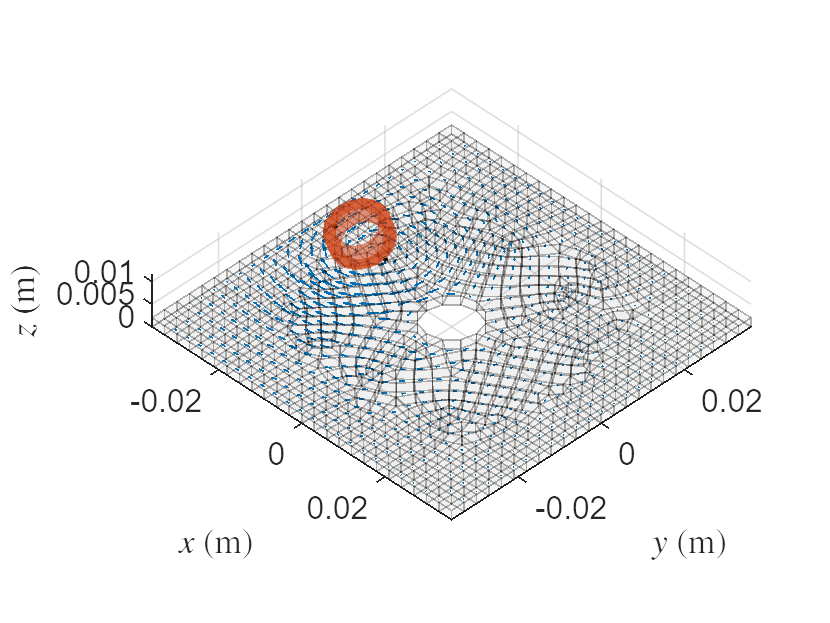

pos = Model.elms_center;
vec = Sol.J_Re;
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear pos vec

PlotWorld3D(Model, EM, Sensor);